## Reflection Coefficient

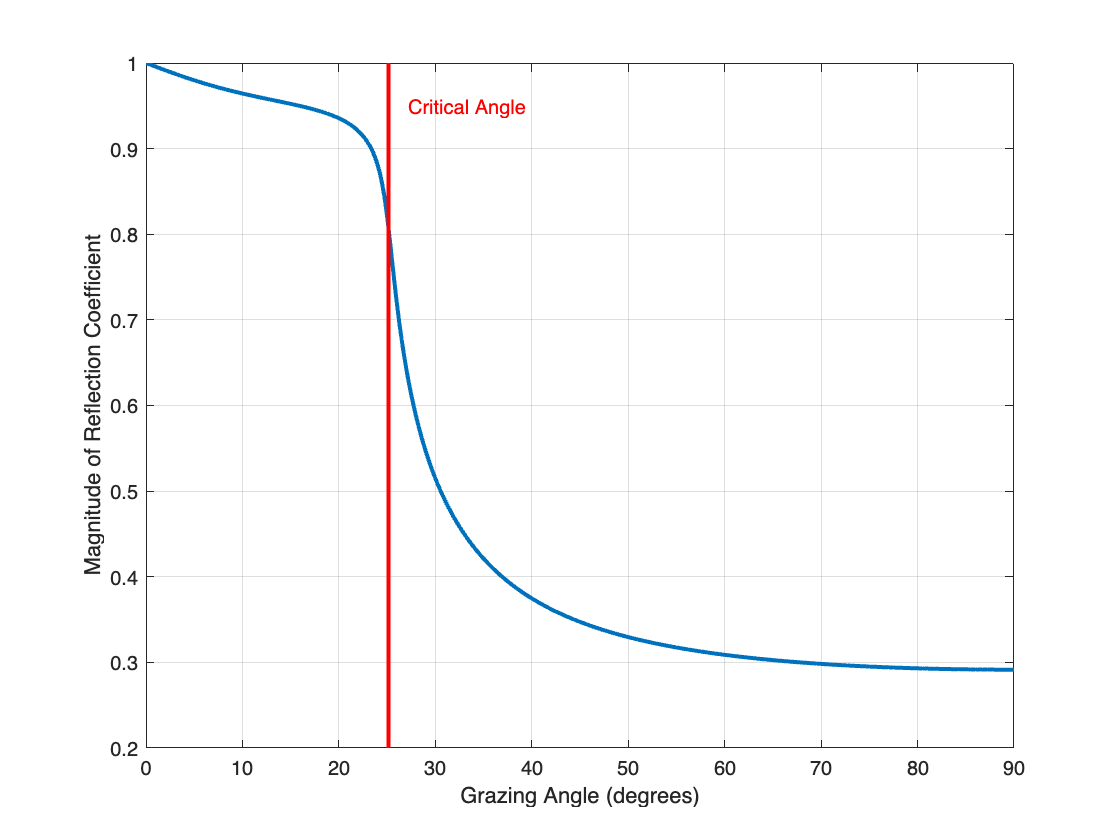

f = 400000;
cw = 1500;
rhow = 1;

cp1 = 1657;
rhop1 = 1.65;
alphap1 = 92;

theta_i_degrees = 0:0.25:90;

R1 = RCoeff(f, theta_i_degrees, cw, cp1, rhop1/rhow, rhow, alphap1);

if cp1 > cw
    crit_angle = acos(cw/cp1)*180/pi;
    disp_angle = crit_angle;
    lineColor = 'red';
    annoteText = 'Critical Angle';
else
    intro_angle = acos(sqrt(((rhop1/rhow)^2 - (cw/cp1)^2)/((rhop1/rhow)^2 - 1)))*180/pi;
    disp_angle = intro_angle;
    lineColor = 'black';
    annoteText = 'Intromission Angle';
end

figure(1)
plot(theta_i_degrees,abs(R1),'linewidth',2)

a1 = gca;
a1.XLabel.String = 'Grazing Angle (degrees)';
a1.YLabel.String = 'Magnitude of Reflection Coefficient';
grid on

line([disp_angle disp_angle],a1.YLim,'linewidth',2,'Color',lineColor)
text(disp_angle+2,0.95,annoteText,'Color',lineColor)

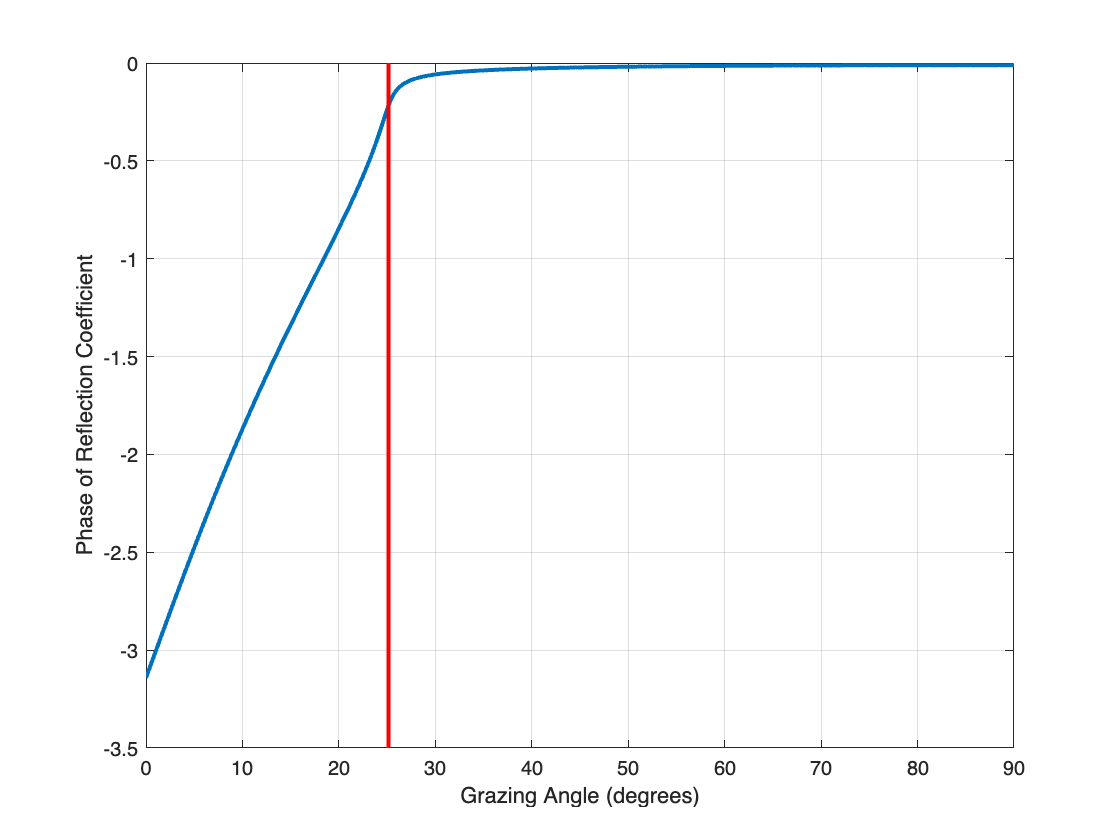


RCAngle = angle(R1);
RCAngle(1) = -RCAngle(1);

figure(2)
plot(theta_i_degrees,RCAngle,'linewidth',2)

a2 = gca;
a2.XLabel.String = 'Grazing Angle (degrees)';
a2.YLabel.String = 'Phase of Reflection Coefficient';
grid on

line([disp_angle disp_angle],a2.YLim,'linewidth',2,'Color',lineColor)